**P1) **. Fie sistemul (exemplul este datorat lui Wilson) .

 (a) Ce se obţine dacă perturbăm membrul drept astfel încât el sa devină [ 32.1 22.9 33.1 30.9 ] ? 

Care este eroarea relativă la intrare, la ieşire şi raportul lor? 

(b) Aceeaşi întrebare dacă perturbăm matricea sistemului:.... Explicaţi şi analizaţi fenomenul.

%Pentru sistemul A*x = B ; unde x = [ 1 1 1 1 ] ^ T
  A = [10 7 8 7 ; 7 5 6 5 ; 8 6 10 9 ; 7 5 9 10 ];
  %A
  B = [ 32 ; 23 ; 33 ; 31 ];
  %B
  x = A \ B;
  %x = [ 1 ; 1 ; 1 ; 1 ]; 
  
  
  %Perturbarea mebrului drept a.i. sa devina [ 32.1 22.9 33.1 30.9] :
  fprintf("a) Perturbarea membrului drept: \n");

a) Perturbarea membrului drept: 


  Bp = [ 32.1 ; 22.9 ; 33.1 ; 30.9 ];
  x_PA = A \ Bp;
  
  err_absB = norm(Bp - B);
  fprintf("Eroare relativa intrare: ");

Eroare relativa intrare: 

  err_relB = err_absB / norm(B)

err_relB = 0.0033

  err_absxPA = norm(x_PA - x);
  fprintf("Eroare relativa iesire: ");

Eroare relativa iesire: 

  err_relxPA = err_absxPA / norm(x)

err_relxPA = 8.1985

  factor_amplificare = err_relxPA / err_relB;
  fprintf("Factor de aplificare : %15.7f",factor_amplificare);

Factor de aplificare :    2460.5672364

  %cond(A)
  
  fprintf("b) Perturbarea matricei sistemului: \n");

b) Perturbarea matricei sistemului: 


  Ap = [ 10 7 8.1 7.2 ; 7.08 5.04 6 5 ; 8 5.98 9.89 9 ; 6.99 4.99 9 9.98 ];
  %Ap
  x_PA = Ap \ B;
  
  err_absA = norm(A - Ap);
  fprintf("Eroarea relativa intrare: ");

Eroarea relativa intrare: 

  err_relA = err_absA / norm(A)

err_relA = 0.0076

  err_absxPA = norm(x_PA - x);
  fprintf("Eroare relativa iesire: ");

Eroare relativa iesire: 

  err_rexPA = err_absxPA / norm(x)

err_rexPA = 81.9848

  fprintf("Factor de aplificare : ");

Factor de aplificare : 

  factor_amplificare = err_relxPA / err_relA

factor_amplificare = 1.0758e+03

**P2)**. Să se studieze condiţionarea matricei Hilbert Hn în raport cu norma euclidiană, n = 10, 15.

for i=10:15
    %matricea Hilbert de grad i
    h = hilb(i);
    %format rat
    %format long
  
    %coditionarea matricii
    fprintf("Conditionarea matricii Hilbert de grad %d : ",i);
    cond(h)
  
    %norma Euclidiana
    fprintf("Norma euclidiana a matricii Hilbert de grad %d: ",i);
    
    norm_e = norm(h,2)  
    fprintf("\n");
    norm_e*norm(invhilb(i),2)
end

Conditionarea matricii Hilbert de grad 10 : 

ans = 1.6025e+13

Norma euclidiana a matricii Hilbert de grad 10: 

norm_e = 1.7519

ans = 1.6026e+13

Conditionarea matricii Hilbert de grad 11 : 

ans = 5.2202e+14

Norma euclidiana a matricii Hilbert de grad 11: 

norm_e = 1.7749

ans = 5.2307e+14

Conditionarea matricii Hilbert de grad 12 : 

ans = 1.6212e+16

Norma euclidiana a matricii Hilbert de grad 12: 

norm_e = 1.7954

ans = 1.7132e+16

Conditionarea matricii Hilbert de grad 13 : 

ans = 4.7864e+17

Norma euclidiana a matricii Hilbert de grad 13: 

norm_e = 1.8138

ans = 5.6279e+17

Conditionarea matricii Hilbert de grad 14 : 

ans = 2.5515e+17

Norma euclidiana a matricii Hilbert de grad 14: 

norm_e = 1.8306

ans = 1.8534e+19

Conditionarea matricii Hilbert de grad 15 : 

ans = 2.4960e+17

Norma euclidiana a matricii Hilbert de grad 15: 

norm_e = 1.8459

ans = 6.1166e+20

**P4)**. Să se studieze teoretic şi experimental condiţionarea problemei determinării rădăcinilor ecuaţiei polinomiale:x n + a1x n−1 + a2x n−2 + · · · + an = 0 (1) cunoscându-se coeficienţii. Se va scrie o rutină pentru calculul numărului de condiţionare al fiecărei rădăcini şi se va studia grafic efectul perturbării fiecărui coeficient cu o variabilă aleatoare normală cu media 0 şi dispersia 10^−10. 

Aplicaţie pentru ecuaţiile (x − 1)(x − 2). . .(x − n) = 0 şi (1) pentru ak = 2−k . Se va lua ca exemplu practic pentru testare n = 20. Ce se întâmplă dacă perturbaţia urmează legea uniformă?

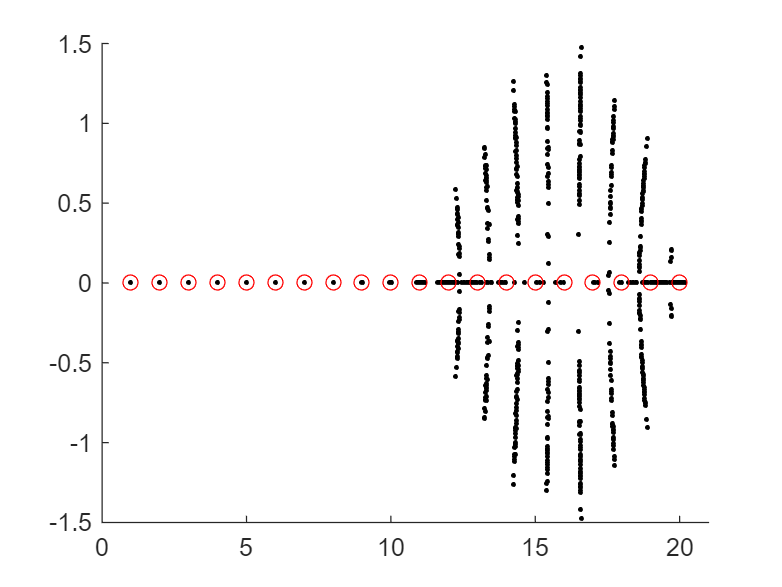

clf; hold on;
n=20;

a=poly(1:n);
 for i=1:100
   vect = randn(1,n+1) * 1e-10;
   ap = a+vect;
   r=roots(ap);
   plot(real(r),imag(r),'.k');
 
 end
 plot(1:n,zeros(1,n),'or');
 xlim([0 n+1]);

 
% Studiem conditionarea pentru a^k = 2^-k
poli2 = 2.^-(1:20);
numar_conditionare=condpol(poli2)

numar_conditionare =     0.2972
    0.2972
    0.5871
    0.5871
    0.8626
    0.8626
    1.1168
    1.1168
    1.9000
    1.8766


r2 = roots(poli2);

figure(2)
nn=length(r2);
h=plot(r2,zeros(1,nn),'k.');

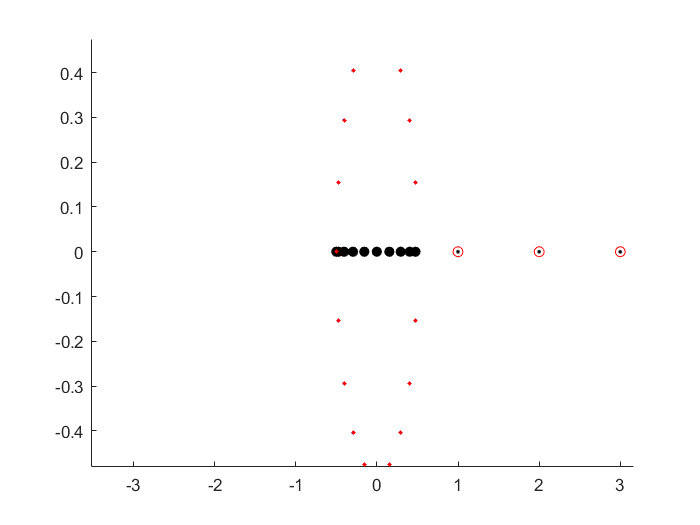

set(h,'Markersize',21);
hold on

for i=1:20
    % distributie normala
    poli1_per_norm = poli2 + normrnd(0, 1e-10, 1, length(poli2));
    r_norm = roots(poli1_per_norm);
    h2=plot(r_norm,'b.');
    hold on
    set(h2,'Markersize',4)
    
    % distributie uniforma
    poli1_per_unif = poli2 + unifrnd(0, 1e-10, 1, length(poli2));
    r_unif = roots(poli1_per_unif);
    h3=plot(r_unif,'r*');
    hold on
    set(h3,'Markersize',2)
end
hold off

function nc = condpol(p,r)
% conditionarea unei ecuatii polinomiale p(x)=0
% p polinom de forma '[...]'
% r radacinile polinomului de forma '[...]'

    if nargin<2
        r = roots(p);
    end
    
    % calculam derivata p'(x)
    % derivata are cu 1 mai putini termeni in polinomul asociat
    n = length(p)-1;                  
    dp = [n:-1:1] .* p(1:end-1); %derivata;
    val_df = polyval(dp,r); % calculam val derivatei in fiecare radacina
    poliv = polyval(abs(p(2:end)),abs(r));
    nc = poliv./(abs(r.*val_df));
end